# Multi-Period Distributed Optimal Power Flow

## Temporally Brute-Forced, Spatially Distributed, Integer-Relaxed NLP.

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep) )
    addpath(genpath('functions\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

T = 1

T = 1

macroItrMax = 100; % Max no. of permissible iterations for optimizing an area
noBatteries = true;
alpha = 1e-3;
% gamma = 1e-1;
gamma = 1e0;
DER_percent = 100;
Batt_percent = DER_percent;
delta_t = 1.00; % one hour
displayTables = true;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;
saveSCDPlots = false;


% delta_t = 0.25; % 15 minutes = 0.25 hours
delta_t = 1.00;
% globalPVCoeff = 2.3;
globalPVCoeff = 1.0;
% lambdaVals = generateLoadProfile(T, 1.0, 1.1, 'upwards')
% lambdaVals = generateLoadProfile(T, 1.0, 1.4, 'upwards')
lambdaVals = generateLoadProfile(T, 1.0, 1.0, 'upwards')

lambdaVals = 1

loadVals = lambdaVals*3

loadVals = 3

% pvCoeffVals = globalPVCoeff*generatePVProfile(T, 0.8, 1.2, 0.9)
pvCoeffVals = globalPVCoeff*generatePVProfile(T, 1.0, 1.0, 1.0)

pvCoeffVals = 1


% costArray0 = [-1.0, 0.0, 0.7, 1.2, 1.5, 1.7, 6.4, 5.4, 2.5, 2.5, 3.2, 3.6, 2.2, 1.9, 1.8, 1.9, 2.9, 5.0, 4.6, 4.5, 4.4, 4.0, 2.8, 4.9]';
costArray0 = [1.6, 3.8, 1.7, 1.8, 2.1, 2.2, 2.4, 2.9, 4.4, 5.1, 4.3, 3.5, 2.8, 2.8, 2.3, 2.0, 2.3, 4.1, 3.4, 6.6, 4.7, 4.7, 5.0, 2.6]';
costArray = choose_middle_T_points(costArray0, T);

V_min = 0.95;
V_max = 1.05;
etta_C = 0.95;
etta_D = 0.95;
soc_min = 0.30;
soc_max = 0.95;

if numAreas == 1
    copf = true;
    myfprintf(verbose, logging, "Centralized OPF it is.");
    simNatureString = "Centralized-OPF";
else
    copf = false;
    myfprintf(verbose, logging, "Perforiming Distributed OPF with %d Areas.", numAreas);
    simNatureString = "Spatially-Distributed-OPF";
end


if strcmp(systemName, "ieee123")
    N = 128;
    m = N-1;
else
    error("Unknown Power System")
end

% actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% N = max(actualBusNums);

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
elseif strcmp(objFunction, "gen_cost")
    strObjectiveFunction = "Cost of Substation Power";
    suffixObj = "genCost";
else
    error("Objective Function NOT recognized.")
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

sysInfo = struct();
sysInfo.N = N;
sysInfo.m = m;
sysInfo.numRelationships = numRelationships;
sysInfo.numAreas = numAreas;
sysInfo.numChildAreas = numChildAreas; % An array of containing no. of 
% child areas for each area
sysInfo.systemName = systemName;
sysInfo.isLeaf = isLeaf;
sysInfo.isRoot = isRoot;
sysInfo.kVA_B = kVA_B;
sysInfo.kV_B = kV_B;
sysInfo.Battery.chargeToPowerRatio = chargeToPowerRatio;
sysInfo.CBTable = CBTable;
PLoss_allT_vs_macroItr = zeros(macroItrMax, 1);
PLoss_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubs_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubs_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubsCost_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubsCost_1toT_vs_macroItr = zeros(T, macroItrMax);

% y_allR_
sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;

simInfo = struct();
simInfo.copf = copf;
simInfo.simNatureString = simNatureString;
simInfo.alpha = alpha;
simInfo.gamma = gamma;
simInfo.DER_percent = DER_percent;
simInfo.Batt_percent = Batt_percent;
simInfo.etta_C = etta_C;
simInfo.etta_D = etta_D;
simInfo.chargeToPowerRatio = chargeToPowerRatio;
simInfo.soc_min = soc_min;
simInfo.soc_max = soc_max;
simInfo.V_min = V_min;
simInfo.V_max = V_max;
simInfo.lambdaVals = lambdaVals;
simInfo.pvCoeffVals = pvCoeffVals;
simInfo.noBatteries = noBatteries;
simInfo.objFunction = objFunction;
simInfo.strObjectiveFunction = strObjectiveFunction;
simInfo.suffixObj = suffixObj;
simInfo.T = T;
if copf
    simInfo.alg.spatial = "CentralizedOPF";
else
    simInfo.alg.spatial = "ENApp";
end
simInfo.costArray = costArray;
simInfo.delta_t = delta_t;
simInfo.alg.temporal = "BruteForce";
simInfo.alg.macroItrMax = macroItrMax;
% stopping criterion
macroItrResidualTolerance = 0.001 ; % Tolerance

simInfo.alg.macroItrResidualTolerance = macroItrResidualTolerance;
simInfo.macroItrsCompleted = 0;
simInfo.alg.correctionStep = a;
simInfo.macroItr = 0;

simInfo.alg.microItrMax = 100;
simInfo.alg.tolfun = 1e-6;
simInfo.alg.stepTol = 1e-6;
simInfo.alg.constraintTol = 1e-6;
simInfo.alg.optimalityTol = 1e-6;

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);


#### Start with the algorithm

if logging && verbose
    error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
elseif logging && ~verbose
    fileOpenedFlag = true;
    fid = fopen(saveLocationFilename, 'w');
elseif ~logging
    logging = verbose;
    fid = 1;
else
    fid = 1;
end

myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
"will be run.\n", T, delta_t*60, delta_t*T);

myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
keepRunningIterations = true;
time_dist = zeros(macroItrMax, numAreas);

maxResidual_vs_macroItr_allT = zeros(macroItrMax, 1);
v1_1 = 1.03^2*ones(numAreas, 1);
v1_1toT = repmat(v1_1, 1, T);

Se_iter = zeros(macroItrMax, numAreas, T);
% Se_iter = zeros(macroItrMax, m, numAreas, T);
V_iter = zeros(macroItrMax, N, numUniqueParents, T);
S12_allRelationships = CBTable.S_childArea;
S12_allRelationships_1toT = repmat(S12_allRelationships, 1, T);
S_parent_1toT = zeros(numAreas, T);
S_Areas_1toT = zeros(N, numAreas, T);
v_Areas_1toT = zeros(N, numAreas, T);
% v1_1toT_vs_macroItr = zeros(numAreas, T, macroItrMax);
v1_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
S12_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
Residuals_1toT_vs_macroItr = zeros(2*numRelationships, T, macroItrMax);

while keepRunningIterations
    for Area = 1:numAreas
    % for Area = 1
    % for Area = [2 3 1 4]
        macroItr = simInfo.macroItr;
        myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr+1, Area);

        v_parAr_1toT = v1_1toT(Area, 1:T)
        S_chArs_1toT = S12_allRelationships_1toT(CBTable.parentArea == Area, 1:T)

        if macroItr == 0
            areaInfo.Area = Area;
        else
            areaInfo = sysInfo.Area{Area};
        end

        [xVals_Area, sysInfo, simInfo, ...
            time_dist] = ...
            ...
            NL_OPF_dist2(sysInfo, simInfo, areaInfo, v_parAr_1toT, S_chArs_1toT, ...
            time_dist, 'verbose', verbose, 'saveToFile', true, 'logging', logging, ...
            'saveSCDPlots', saveSCDPlots);
        
        nVars1_Area = length(xVals_Area)/T;
        xVals_Area_1toT = reshape(xVals_Area, nVars1_Area, T)
        % macroItr = simInfo.macroItr;
        
        myfprintf(true, fid, "Current Macro-iteration %d: OPF for Area %d computed.\n", macroItr+1, Area)
        areaInfo = sysInfo.Area{Area};
        N_Area = areaInfo.N_Area;
        m_Area = areaInfo.m_Area;
    
        % indices_Pij = areaInfo.indices_Pij;
        P_Area_1toT = xVals_Area(areaInfo.indices_Pij)'; %m_Areax1
        Q_Area_1toT = xVals_Area(areaInfo.indices_Qij)'; %m_Areax1
        S_Area_1toT = complex(P_Area_1toT, Q_Area_1toT); %m_Areax1
        vAll_Area_1toT = xVals_Area(areaInfo.indices_vAllj)'; %N_Areax1
        
        PSubs_Area_1toT = P_Area_1toT(1, 1:T);
        S_parent_1toT(Area, 1:T) = S_Area_1toT(1, 1:T);

        v_Areas_1toT(1:N_Area, Area, 1:T) = vAll_Area_1toT;
        S_Areas_1toT(1:m_Area, Area, 1:T) = S_Area_1toT;  % Storing all the S flow of the Area
        
        PLoss_allT_vs_macroItr(macroItr+1) = PLoss_allT_vs_macroItr(macroItr+1) + areaInfo.PLoss_allT;
        PLoss_1toT_vs_macroItr(1:T, macroItr+1) = PLoss_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PLoss_1toT;
        PSubs_allT_vs_macroItr(macroItr+1) = PSubs_allT_vs_macroItr(macroItr+1) + areaInfo.PSubs_allT;
        PSubs_1toT_vs_macroItr(1:T, macroItr+1) = PSubs_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubs_1toT;
        PSubsCost_allT_vs_macroItr(macroItr+1) = PSubsCost_allT_vs_macroItr(macroItr+1) + areaInfo.PSubsCost_allT;
        PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) = PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubsCost_1toT;

        sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;  
        sysInfo.Ploss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
        sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
        sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
        sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
        sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
        % keyboard
    end
    
    myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr+1);
    % first let's quickly compute system losses for the macroItr first and
    % store them
    
    if ~copf
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);

            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent_1toT = reshape(S_Areas_1toT(parentAreaConnectingBus - 1, parAr, 1:T), 1, T)
            S12_intoChild_1toT = reshape(S_parent_1toT(chAr, 1:T), 1, T)
    
            delta_S12_1toT = S12_fromParent_1toT - S12_intoChild_1toT
    
            v_parentSide_1toT = reshape(v_Areas_1toT(parentAreaConnectingBus, parAr, 1:T), 1, T);
            v_childSide_1toT = v1_1toT(chAr, 1:T);
    
            v1_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = v_parentSide_1toT;
            S12_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = S12_intoChild_1toT;

            delta_v_1toT = v_parentSide_1toT - v_childSide_1toT
    
            Residual_Area_1toT = reshape([delta_S12_1toT; delta_v_1toT], 2*T, 1);
            
            [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));

            row = lin_idx;
            myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr+1, currentMaxResidual_1toT, row);

            
            if currentMaxResidual_1toT > maxResidual_vs_macroItr_allT(macroItr+1)
                maxResidual_vs_macroItr_allT(macroItr+1) = currentMaxResidual_1toT;
                myfprintf(true, "It is even bigger than the previous biggest residual.\n");
            end
    
        end
        
        myfprintf(true, "Macro-iteration %d: Checking for convergence among all connected areas completed.\n", macroItr+1);
        if macroItr == macroItrMax - 1
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif currentMaxResidual_1toT < macroItrResidualTolerance
            myfprintf(true, "MPOPF for Horizon T = %d Converged in %d macro-iterations!\n", T, macroItr+1);
            keepRunningIterations = false;
            maxResidual_vs_macroItr_allT = maxResidual_vs_macroItr_allT(1:macroItr+1);
    
        else
            myfprintf(true, "MPOPF for Horizon T = %d , Still yet to converge after %d macro-iterations, continuing.\n", T, macroItr+1)
            %Communication-
            myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                "let's exchange boundary variables.\n")

            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);

                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);

                areaInfo_par = sysInfo.Area{parAr};
                areaInfo_ch = sysInfo.Area{chAr};
    
                
                V_iter(macroItr+1, busParTo, parAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T) ;

                Se_iter(macroItr+1, chAr, 1:T) = S_parent_1toT(chAr, 1:T);
    
                if macroItr >= 2
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = a(2)*reshape(V_iter(macroItr, busParTo, parAr, 1:T), 1, T) + ...
                        a(1)*reshape(V_iter(macroItr+1, busParTo, parAr, 1:T), 1, T) + ...
                        (1-sum(a))*reshape(v_Areas_1toT(busParTo, parAr, 1:T), 1, T)
                    disp(v1_1toT(char, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)

                    S12_allRelationships_1toT(relationshipNum, 1:T) = a(2)*reshape(Se_iter(macroItr-1, chAr, 1:T), 1, T)+...
                        a(1)*reshape(Se_iter(macroItr, chAr, 1:T), 1, T)+...
                        (1-sum(a))*S_parent_1toT(chAr, 1:T);
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));
                else
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T)
                    disp(v1_1toT(chAr, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)
                    S12_allRelationships_1toT(relationshipNum, 1:T) = S_parent_1toT(chAr, 1:T)
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));

    
                end
    
            end

            simInfo.macroItr = macroItr + 1;

        end

        
    else
        keepRunningIterations = false;
        myfprintf(verbose, "Centralized MPOPF for %d Horizons ended.\n", T);
    end

end

Macro-iteration 1: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =      0
     0


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     2.401e-02  
    1         370    9.680035e-11     2.755e-02     1.000e+00     4.964e-01     1.646e-01  
    2         555    3.232870e-04     1.095e-06     1.000e+00     4.493e-02     2.603e-02  
    3         740    3.231043e-04     3.284e-08     1.000e+00     4.332e-04     1.782e-04  
    4         925    3.221860e-04     8.024e-07     1.000e+00     2.144e-03     1.682e-04  
    5        1110    3.180630e-04     1.805e-05     1.000e+00     1.018e-02     1.272e-04  
    6        1295    3.125603e-04     6.853e-05     1.000e+00     1.974e-02     8.130e-05  
    7        1480    3.126363e-04     5.060e-05     1.000e+00     1.712e-02     1.889e-04  
    8        1665    3.136952e-04     6.284e-06     1.000e+00     5.978e-03     5.

xVals_Area_1toT =     0.1649
    0.1649
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.1302
    0.1258
    0.0217


Macro-iteration 1: Running OPF for Area 2.


v_parAr_1toT = 1.0609

S_chArs_1toT = 0

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     1.415e-02  
    1         172    7.497585e-11     1.430e-02     1.000e+00     3.847e-01     1.192e-01  
    2         258    3.293164e-04     1.654e-07     1.000e+00     2.825e-02     1.355e-02  
    3         344    3.292336e-04     1.584e-08     1.000e+00     2.903e-04     1.224e-04  
    4         430    3.288249e-04     3.828e-07     1.000e+00     1.431e-03     1.109e-04  
    5         516    3.270730e-04     8.220e-06     1.000e+00     6.648e-03     7.412e-05  
    6         602    3.253092e-04     2.699e-05     1.000e+00     1.210e-02     4.081e-05  
    7         688    3.263322e-04     2.339e-09     1.000e+00     1.409e-04     4.048e-05  
    8         774    3.263033e-04     1.454e-08     1.000e+00     3.400e-04     4.

xVals_Area_1toT =     0.1195
    0.1195
    0.1108
    0.1021
    0.0087
    0.0043
    0.0934
    0.0087
    0.0043
    0.0847


Macro-iteration 1: Running OPF for Area 3.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.447046e-11     2.689e-02     1.000e+00     4.395e-01     1.636e-01  
    2         276    2.560137e-04     2.921e-07     1.000e+00     4.733e-02     2.541e-02  
    3         368    2.559939e-04     3.466e-09     1.000e+00     1.440e-04     5.857e-05  
    4         460    2.558918e-04     8.578e-08     1.000e+00     7.150e-04     5.709e-05  
    5         552    2.554170e-04     2.008e-06     1.000e+00     3.453e-03     4.991e-05  
    6         645    2.545220e-04     2.960e-08     1.000e+00     1.432e-02     3.781e-05  
    7         738    2.544934e-04     3.578e-10     1.000e+00     2.453e-03     3.473e-05  
    8         830    2.544816e-04     7.088e-08     1.000e+00     6.094e-04     3.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 1: Running OPF for Area 4.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.635270e-10     9.558e-02     1.000e+00     8.348e-01     3.087e-01  
    2         750    1.013198e-03     6.231e-06     1.000e+00     1.710e-01     9.061e-02  
    3        1000    1.013044e-03     2.075e-08     1.000e+00     4.405e-04     1.407e-04  
    4        1250    1.012593e-03     1.355e-07     1.000e+00     1.150e-03     1.323e-04  
    5        1500    1.010592e-03     2.941e-06     1.000e+00     5.366e-03     1.225e-04  
    6        1751    1.008176e-03     1.566e-08     1.000e+00     1.655e-02     1.376e-04  
    7        2002    1.008119e-03     4.256e-11     1.000e+00     1.988e-03     5.156e-05  
    8        2252    1.008066e-03     1.231e-07     1.000e+00     1.093e-03     4.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = -3.1159e-21 + 1.4551e-21i

S12_intoChild_1toT = 0.1195 - 0.0005i

delta_S12_1toT = -0.1195 + 0.0005i

delta_v_1toT = -0.0034

Macro-iteration 1: Current Biggest Residual is 1.194878e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 3.7352e-23 - 9.8237e-21i

S12_intoChild_1toT = 0.1638 - 0.0004i

delta_S12_1toT = -0.1638 + 0.0004i

delta_v_1toT = -0.0047

Macro-iteration 1: Current Biggest Residual is 1.638328e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = -4.1632e-21 + 1.0405e-20i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -0.3097 + 0.0011i

delta_v_1toT = -0.0036

Macro-iteration 1: Current Biggest Residual is 3.097104e-01 at index 1.


It is even bigger than the previous biggest residual.


Macro-iteration 1: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0575
    1.0609
    1.0609


    1.0575



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1195 - 0.0005i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


   0.1195 - 0.0005i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0575
    1.0562
    1.0609


    1.0562



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1195 - 0.0005i
   0.1638 - 0.0004i
   0.0000 + 0.0000i


   0.1638 - 0.0004i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0575
    1.0562
    1.0573


    1.0573



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1195 - 0.0005i
   0.1638 - 0.0004i
   0.3097 - 0.0011i


   0.3097 - 0.0011i



Macro-iteration 2: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.1195 - 0.0005i
   0.1638 - 0.0004i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     1.638e-01     1.000e+00     0.000e+00     2.401e-02  
    1         372    8.139002e-11     8.355e-02     4.900e-01     5.142e-01     2.195e-01  
    2         557    1.917650e-03     4.862e-02     1.000e+00     6.126e-01     1.496e-01  
    3         742    2.530515e-03     1.439e-06     1.000e+00     9.353e-02     1.860e-02  
    4         927    2.530382e-03     2.004e-08     1.000e+00     3.732e-04     1.407e-04  
    5        1112    2.529701e-03     4.917e-07     1.000e+00     1.846e-03     1.341e-04  
    6        1297    2.526650e-03     1.108e-05     1.000e+00     8.759e-03     1.027e-04  
    7        1482    2.523073e-03     3.396e-05     1.000e+00     1.524e-02     7.514e-05  
    8        1667    2.522562e-03     3.729e-05     1.000e+00     1.598e-02     2.

xVals_Area_1toT =     0.4505
    0.4505
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.4150
    0.4102
    0.0217


Macro-iteration 2: Running OPF for Area 2.


v_parAr_1toT = 1.0575

S_chArs_1toT = 0.3097 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     1.415e-02  
    1         174    7.779142e-11     1.580e-01     4.900e-01     5.341e-01     2.101e-01  
    2         260    2.333275e-03     4.497e-02     1.000e+00     6.419e-01     1.372e-01  
    3         346    3.089113e-03     7.269e-07     1.000e+00     1.016e-01     1.669e-02  
    4         432    3.089053e-03     1.299e-08     1.000e+00     2.534e-04     1.108e-04  
    5         518    3.088742e-03     3.140e-07     1.000e+00     1.249e-03     1.014e-04  
    6         604    3.087404e-03     6.750e-06     1.000e+00     5.809e-03     7.130e-05  
    7         690    3.086016e-03     2.295e-05     1.000e+00     1.076e-02     4.030e-05  
    8         776    3.086813e-03     2.495e-09     1.000e+00     1.447e-04     3.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4047
    0.0087
    0.0043
    0.3955


Macro-iteration 2: Running OPF for Area 3.


v_parAr_1toT = 1.0562


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.616e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.416663e-11     2.687e-02     1.000e+00     4.274e-01     1.636e-01  
    2         276    2.570296e-04     2.647e-07     1.000e+00     4.751e-02     2.551e-02  
    3         368    2.570110e-04     3.455e-09     1.000e+00     1.396e-04     5.847e-05  
    4         460    2.569150e-04     8.547e-08     1.000e+00     6.930e-04     5.695e-05  
    5         552    2.564689e-04     2.000e-06     1.000e+00     3.346e-03     4.954e-05  
    6         645    2.556279e-04     2.989e-08     1.000e+00     1.388e-02     3.898e-05  
    7         738    2.556010e-04     3.634e-10     1.000e+00     2.381e-03     3.379e-05  
    8         830    2.555900e-04     6.835e-08     1.000e+00     5.854e-04     3.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 2: Running OPF for Area 4.


v_parAr_1toT = 1.0573


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.627634e-10     9.554e-02     1.000e+00     8.220e-01     3.087e-01  
    2         750    1.016019e-03     5.599e-06     1.000e+00     1.715e-01     9.089e-02  
    3        1000    1.015878e-03     1.985e-08     1.000e+00     4.196e-04     1.376e-04  
    4        1250    1.015453e-03     1.387e-07     1.000e+00     1.132e-03     1.291e-04  
    5        1500    1.013577e-03     2.974e-06     1.000e+00     5.254e-03     1.129e-04  
    6        1751    1.011391e-03     1.429e-08     1.000e+00     1.588e-02     1.322e-04  
    7        2002    1.011340e-03     3.348e-11     1.000e+00     1.813e-03     4.878e-05  
    8        2252    1.011288e-03     1.342e-07     1.000e+00     1.113e-03     4.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.1195 - 0.0005i

S12_intoChild_1toT = 0.4320 - 0.0049i

delta_S12_1toT = -0.3125 + 0.0044i

delta_v_1toT = -0.0067

Macro-iteration 2: Current Biggest Residual is 3.125000e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0004i

S12_intoChild_1toT = 0.1638 - 0.0005i

delta_S12_1toT = -6.9729e-07 + 4.4459e-06i

delta_v_1toT = -0.0094

Macro-iteration 2: Current Biggest Residual is 9.442278e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0011i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -1.8016e-06 + 2.9067e-06i

delta_v_1toT = -0.0147

Macro-iteration 2: Current Biggest Residual is 1.465615e-02 at index 2.


Macro-iteration 2: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0507
    1.0562
    1.0573


    1.0507



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4320 - 0.0049i
   0.1638 - 0.0004i
   0.3097 - 0.0011i


   0.4320 - 0.0049i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0507
    1.0467
    1.0573


    1.0467



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4320 - 0.0049i
   0.1638 - 0.0005i
   0.3097 - 0.0011i


   0.1638 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0507
    1.0467
    1.0427


    1.0427



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4320 - 0.0049i
   0.1638 - 0.0005i
   0.3097 - 0.0011i


   0.3097 - 0.0011i



Macro-iteration 3: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4320 - 0.0049i
   0.1638 - 0.0005i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.320e-01     1.000e+00     0.000e+00     2.401e-02  
    1         374    5.316660e-11     3.282e-01     2.401e-01     4.195e-01     1.826e-01  
    2         561    1.429456e-03     1.674e-01     4.900e-01     6.990e-01     1.212e-01  
    3         746    5.754235e-03     8.096e-02     1.000e+00     1.020e+00     1.240e-01  
    4         931    6.691319e-03     2.207e-06     1.000e+00     1.641e-01     2.138e-02  
    5        1116    6.691229e-03     1.253e-08     1.000e+00     3.165e-04     1.112e-04  
    6        1301    6.690740e-03     3.070e-07     1.000e+00     1.565e-03     1.060e-04  
    7        1486    6.688554e-03     6.906e-06     1.000e+00     7.413e-03     8.098e-05  
    8        1671    6.685951e-03     2.222e-05     1.000e+00     1.321e-02     6.

xVals_Area_1toT =     0.7671
    0.7671
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.7302
    0.7244
    0.0217


Macro-iteration 3: Running OPF for Area 2.


v_parAr_1toT = 1.0507

S_chArs_1toT = 0.3097 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     1.415e-02  
    1         174    7.754852e-11     1.580e-01     4.900e-01     5.316e-01     2.101e-01  
    2         260    2.340611e-03     4.542e-02     1.000e+00     6.402e-01     1.372e-01  
    3         346    3.108934e-03     7.144e-07     1.000e+00     1.033e-01     1.679e-02  
    4         432    3.108882e-03     1.213e-08     1.000e+00     2.396e-04     1.070e-04  
    5         518    3.108603e-03     2.933e-07     1.000e+00     1.181e-03     9.823e-05  
    6         604    3.107408e-03     6.301e-06     1.000e+00     5.489e-03     7.058e-05  
    7         690    3.106189e-03     2.102e-05     1.000e+00     1.007e-02     3.960e-05  
    8         776    3.106892e-03     2.238e-09     1.000e+00     1.379e-04     3.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4047
    0.0087
    0.0043
    0.3955


Macro-iteration 3: Running OPF for Area 3.


v_parAr_1toT = 1.0467


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.356079e-11     2.684e-02     1.000e+00     4.053e-01     1.636e-01  
    2         276    2.591143e-04     2.147e-07     1.000e+00     4.790e-02     2.572e-02  
    3         368    2.590976e-04     3.452e-09     1.000e+00     1.317e-04     5.845e-05  
    4         460    2.590122e-04     8.535e-08     1.000e+00     6.538e-04     5.683e-05  
    5         552    2.586153e-04     1.995e-06     1.000e+00     3.156e-03     4.897e-05  
    6         645    2.578722e-04     3.239e-08     1.000e+00     1.308e-02     4.134e-05  
    7         738    2.578494e-04     3.472e-10     1.000e+00     2.161e-03     3.190e-05  
    8         830    2.578398e-04     6.776e-08     1.000e+00     5.579e-04     3.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 3: Running OPF for Area 4.


v_parAr_1toT = 1.0427


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.595360e-10     9.542e-02     1.000e+00     7.762e-01     3.087e-01  
    2         750    1.028203e-03     3.382e-06     1.000e+00     1.738e-01     9.209e-02  
    3        1000    1.028115e-03     1.624e-08     1.000e+00     3.348e-04     1.244e-04  
    4        1250    1.027772e-03     1.687e-07     1.000e+00     1.102e-03     1.149e-04  
    5        1500    1.026341e-03     3.302e-06     1.000e+00     4.894e-03     9.457e-05  
    6        1751    1.024987e-03     1.278e-08     1.000e+00     1.322e-02     1.092e-04  
    7        2002    1.024961e-03     8.530e-12     1.000e+00     1.050e-03     3.715e-05  
    8        2253    1.024912e-03     2.195e-12     1.000e+00     1.430e-03     3.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4320 - 0.0049i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -2.0448e-05 + 5.6119e-05i

delta_v_1toT = -0.0074

Macro-iteration 3: Current Biggest Residual is 7.398858e-03 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0005i

S12_intoChild_1toT = 0.1638 - 0.0005i

delta_S12_1toT = -1.8600e-06 + 4.5941e-06i

delta_v_1toT = -0.0074

Macro-iteration 3: Current Biggest Residual is 7.383999e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0011i

S12_intoChild_1toT = 0.3097 - 0.0010i

delta_S12_1toT = -1.2626e-05 - 9.3245e-05i

delta_v_1toT = -0.0067

Macro-iteration 3: Current Biggest Residual is 6.740831e-03 at index 2.


Macro-iteration 3: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 3 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0437
    1.0467
    1.0427


***Macro-iteration 3 Communication Power:****


   0.4163 - 0.0047i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0437
    1.0397
    1.0427


***Macro-iteration 3 Communication Power:****


   0.1638 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0437
    1.0397
    1.0363


***Macro-iteration 3 Communication Power:****


   0.3097 - 0.0010i



Macro-iteration 4: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4163 - 0.0047i
   0.1638 - 0.0005i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.163e-01     1.000e+00     0.000e+00     2.401e-02  
    1         374    5.250743e-11     3.164e-01     2.401e-01     4.108e-01     1.788e-01  
    2         561    1.373650e-03     1.614e-01     4.900e-01     6.825e-01     1.163e-01  
    3         746    5.528731e-03     7.762e-02     1.000e+00     9.866e-01     1.189e-01  
    4         931    6.428484e-03     2.103e-06     1.000e+00     1.570e-01     2.022e-02  
    5        1116    6.428390e-03     1.286e-08     1.000e+00     3.202e-04     1.127e-04  
    6        1301    6.427889e-03     3.152e-07     1.000e+00     1.583e-03     1.074e-04  
    7        1486    6.425652e-03     7.091e-06     1.000e+00     7.500e-03     8.208e-05  
    8        1671    6.423013e-03     2.245e-05     1.000e+00     1.326e-02     7.

xVals_Area_1toT =     0.7512
    0.7512
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.7144
    0.7086
    0.0217


Macro-iteration 4: Running OPF for Area 2.


v_parAr_1toT = 1.0437

S_chArs_1toT = 0.3097 - 0.0010i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     1.415e-02  
    1         174    7.729442e-11     1.580e-01     4.900e-01     5.295e-01     2.102e-01  
    2         260    2.348410e-03     4.589e-02     1.000e+00     6.388e-01     1.372e-01  
    3         346    3.130003e-03     7.047e-07     1.000e+00     1.051e-01     1.692e-02  
    4         432    3.129958e-03     1.125e-08     1.000e+00     2.254e-04     1.031e-04  
    5         518    3.129711e-03     2.720e-07     1.000e+00     1.111e-03     9.674e-05  
    6         604    3.128655e-03     5.842e-06     1.000e+00     5.163e-03     6.982e-05  
    7         690    3.127589e-03     1.922e-05     1.000e+00     9.405e-03     3.894e-05  
    8         776    3.128204e-03     1.986e-09     1.000e+00     1.315e-04     3.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4047
    0.0087
    0.0043
    0.3955


Macro-iteration 4: Running OPF for Area 3.


v_parAr_1toT = 1.0397


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.311070e-11     2.682e-02     1.000e+00     3.911e-01     1.636e-01  
    2         276    2.607148e-04     1.815e-07     1.000e+00     4.819e-02     2.588e-02  
    3         368    2.606993e-04     3.471e-09     1.000e+00     1.268e-04     5.861e-05  
    4         460    2.606201e-04     8.576e-08     1.000e+00     6.293e-04     5.690e-05  
    5         552    2.602526e-04     2.002e-06     1.000e+00     3.037e-03     4.865e-05  
    6         645    2.595732e-04     3.439e-08     1.000e+00     1.256e-02     4.311e-05  
    7         738    2.595541e-04     3.035e-10     1.000e+00     1.932e-03     3.037e-05  
    8         830    2.595450e-04     7.229e-08     1.000e+00     5.581e-04     2.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 4: Running OPF for Area 4.


v_parAr_1toT = 1.0363


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.580859e-10     9.539e-02     1.000e+00     7.601e-01     3.087e-01  
    2         750    1.033817e-03     2.622e-06     1.000e+00     1.748e-01     9.264e-02  
    3        1000    1.033750e-03     1.473e-08     1.000e+00     2.997e-04     1.185e-04  
    4        1250    1.033434e-03     1.947e-07     1.000e+00     1.113e-03     1.082e-04  
    5        1500    1.032170e-03     3.549e-06     1.000e+00     4.775e-03     8.883e-05  
    6        1751    1.031113e-03     1.345e-08     1.000e+00     1.209e-02     9.807e-05  
    7        2001    1.031090e-03     8.588e-08     1.000e+00     7.410e-04     3.262e-05  
    8        2252    1.031031e-03     7.417e-12     1.000e+00     1.833e-03     4.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 4: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4164 - 0.0047i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -0.0157 + 0.0002i

delta_v_1toT = -1.4766e-06

Macro-iteration 4: Current Biggest Residual is 1.566079e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0005i

S12_intoChild_1toT = 0.1638 - 0.0005i

delta_S12_1toT = -2.0435e-06 + 6.2871e-06i

delta_v_1toT = -2.3945e-06

Macro-iteration 4: Current Biggest Residual is 6.610911e-06 at index 1.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0010i

S12_intoChild_1toT = 0.3097 - 0.0010i

delta_S12_1toT = -9.1675e-06 + 8.2015e-06i

delta_v_1toT = -0.0074

Macro-iteration 4: Current Biggest Residual is 7.365146e-03 at index 2.


Macro-iteration 4: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 4 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0437
    1.0397
    1.0363


***Macro-iteration 4 Communication Power:****


   0.4320 - 0.0050i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0437
    1.0397
    1.0363


***Macro-iteration 4 Communication Power:****


   0.1638 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0437
    1.0397
    1.0293


***Macro-iteration 4 Communication Power:****


   0.3097 - 0.0010i



Macro-iteration 5: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4320 - 0.0050i
   0.1638 - 0.0005i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.320e-01     1.000e+00     0.000e+00     2.401e-02  
    1         374    5.317189e-11     3.283e-01     2.401e-01     4.195e-01     1.826e-01  
    2         561    1.429632e-03     1.674e-01     4.900e-01     6.991e-01     1.212e-01  
    3         746    5.754946e-03     8.097e-02     1.000e+00     1.020e+00     1.240e-01  
    4         931    6.692148e-03     2.208e-06     1.000e+00     1.641e-01     2.138e-02  
    5        1116    6.692057e-03     1.255e-08     1.000e+00     3.166e-04     1.113e-04  
    6        1301    6.691568e-03     3.074e-07     1.000e+00     1.565e-03     1.061e-04  
    7        1486    6.689380e-03     6.916e-06     1.000e+00     7.416e-03     8.104e-05  
    8        1671    6.686775e-03     2.224e-05     1.000e+00     1.322e-02     6.

xVals_Area_1toT =     0.7672
    0.7672
    0.0043
    0.0217
    0.0087
    0.0130
    0.0087
    0.7303
    0.7244
    0.0217


Macro-iteration 5: Running OPF for Area 2.


v_parAr_1toT = 1.0437

S_chArs_1toT = 0.3097 - 0.0010i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.097e-01     1.000e+00     0.000e+00     1.415e-02  
    1         174    7.729481e-11     1.580e-01     4.900e-01     5.295e-01     2.102e-01  
    2         260    2.348522e-03     4.590e-02     1.000e+00     6.388e-01     1.372e-01  
    3         346    3.130183e-03     7.048e-07     1.000e+00     1.051e-01     1.692e-02  
    4         432    3.130137e-03     1.125e-08     1.000e+00     2.254e-04     1.030e-04  
    5         518    3.129891e-03     2.720e-07     1.000e+00     1.111e-03     9.674e-05  
    6         604    3.128834e-03     5.841e-06     1.000e+00     5.162e-03     6.982e-05  
    7         690    3.127769e-03     1.921e-05     1.000e+00     9.403e-03     3.893e-05  
    8         776    3.128384e-03     1.985e-09     1.000e+00     1.314e-04     3.

xVals_Area_1toT =     0.4320
    0.4320
    0.4226
    0.4136
    0.0087
    0.0043
    0.4048
    0.0087
    0.0043
    0.3955


Macro-iteration 5: Running OPF for Area 3.


v_parAr_1toT = 1.0397


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.310937e-11     2.682e-02     1.000e+00     3.910e-01     1.636e-01  
    2         276    2.607196e-04     1.814e-07     1.000e+00     4.819e-02     2.588e-02  
    3         368    2.607041e-04     3.471e-09     1.000e+00     1.267e-04     5.861e-05  
    4         460    2.606249e-04     8.576e-08     1.000e+00     6.293e-04     5.690e-05  
    5         552    2.602575e-04     2.003e-06     1.000e+00     3.037e-03     4.865e-05  
    6         645    2.595783e-04     3.440e-08     1.000e+00     1.256e-02     4.311e-05  
    7         738    2.595592e-04     3.033e-10     1.000e+00     1.931e-03     3.036e-05  
    8         830    2.595501e-04     7.231e-08     1.000e+00     5.581e-04     2.

xVals_Area_1toT =     0.1638
    0.1638
    0.0173
    0.0087
    0.0087
    0.0043
    0.1377
    0.0043
    0.1334
    0.0087


Macro-iteration 5: Running OPF for Area 4.


v_parAr_1toT = 1.0293


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.564977e-10     9.535e-02     1.000e+00     7.454e-01     3.087e-01  
    2         750    1.040188e-03     1.954e-06     1.000e+00     1.760e-01     9.325e-02  
    3        1000    1.040143e-03     1.313e-08     1.000e+00     2.649e-04     1.119e-04  
    4        1250    1.039850e-03     2.359e-07     1.000e+00     1.145e-03     1.005e-04  
    5        1500    1.038751e-03     3.843e-06     1.000e+00     4.646e-03     8.227e-05  
    6        1751    1.037958e-03     1.470e-08     1.000e+00     1.095e-02     7.799e-05  
    7        2001    1.037942e-03     3.684e-08     1.000e+00     4.608e-04     3.249e-05  
    8        2252    1.037856e-03     1.522e-11     1.000e+00     1.852e-03     3.

xVals_Area_1toT =     0.3097
    0.3097
    0.3097
    0.0260
    0.0217
    0.0130
    0.0087
    0.1880
    0.0260
    0.0173


Macro-iteration 5: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4320 - 0.0050i

S12_intoChild_1toT = 0.4320 - 0.0050i

delta_S12_1toT = -1.5777e-05 + 8.8136e-06i

delta_v_1toT = -3.5057e-04

Macro-iteration 5: Current Biggest Residual is 3.505746e-04 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1638 - 0.0005i

S12_intoChild_1toT = 0.1638 - 0.0005i

delta_S12_1toT = -1.9536e-07 + 2.0080e-06i

delta_v_1toT = -3.4935e-04

Macro-iteration 5: Current Biggest Residual is 3.493496e-04 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3097 - 0.0010i

S12_intoChild_1toT = 0.3097 - 0.0011i

delta_S12_1toT = -8.0383e-06 + 5.7896e-05i

delta_v_1toT = -3.7159e-04

Macro-iteration 5: Current Biggest Residual is 3.715938e-04 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 5: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 Converged in 5 macro-iterations!


if ~noBatteries && saveSCDPlots
    for Area = 1:numAreas
        areaInfo = sysInfo.Area{Area};
        xValsArea_1toT = areaInfo.xvals;
        checkForSCD(sysInfo, simInfo, areaInfo, T, xValsArea_1toT, 'savePlots', true);
    end
end

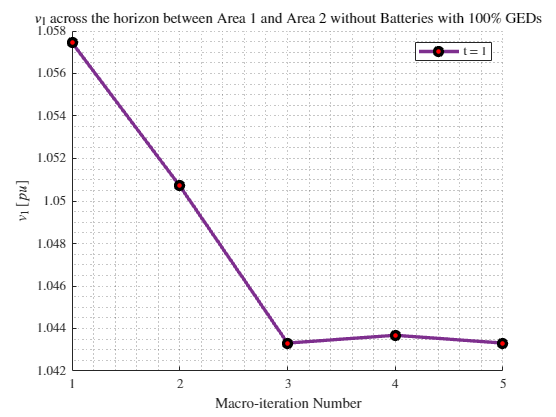

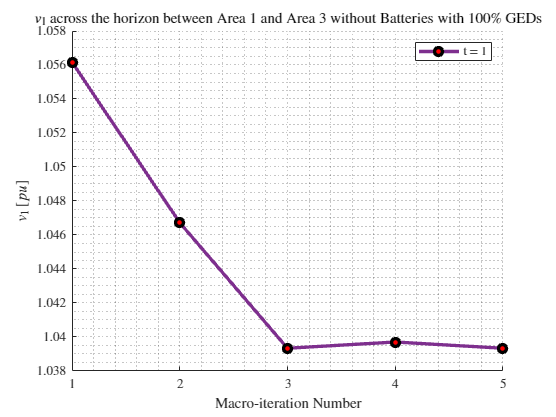

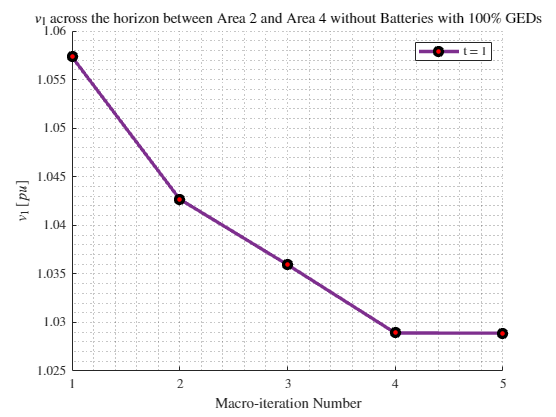

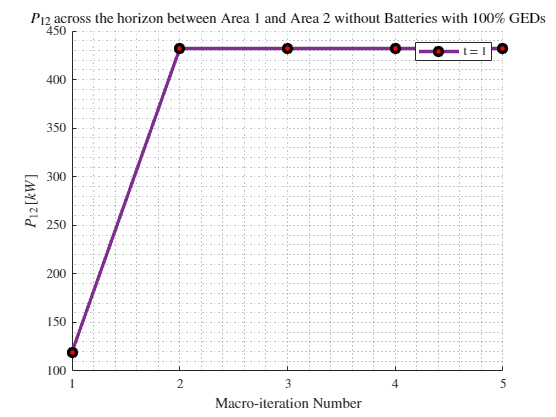

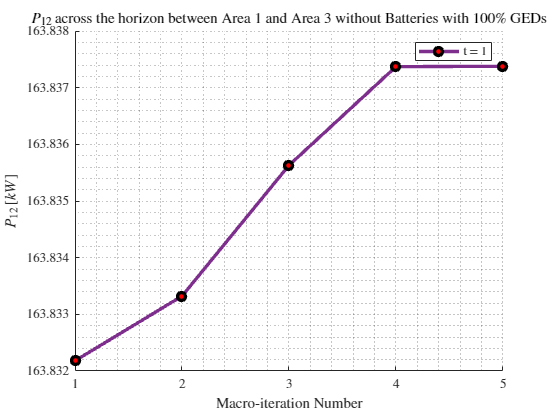

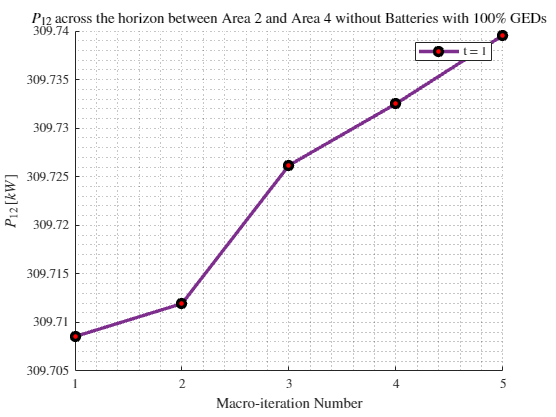

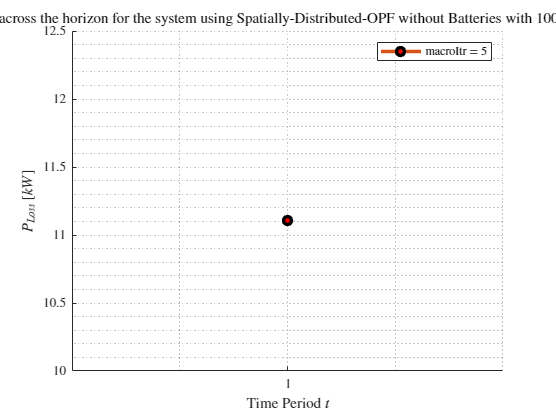

PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr(1:macroItr+1);
PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr(:, 1:macroItr+1);
PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr(1:macroItr+1);
PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr(:, 1:macroItr+1);
PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr(1:macroItr+1);
PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr(:, 1:macroItr+1);
v1_1toT_vs_macroItr = v1_1toT_vs_macroItr(:, :, 1:macroItr+1);
S12_1toT_vs_macroItr = S12_1toT_vs_macroItr(:, :, 1:macroItr+1);
P12_1toT_vs_macroItr = real(S12_1toT_vs_macroItr);
time_dist = time_dist(1:macroItr+1, :);

results = struct();
results.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
results.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
results.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
results.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
results.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
results.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
results.v1_1toT_vs_macroItr = v1_1toT_vs_macroItr;
results.S12_1toT_vs_macroItr = S12_1toT_vs_macroItr;


results.P12_1toT_vs_macroItr = P12_1toT_vs_macroItr;
% plot_relationships_over_time(results, simInfo, sysInfo)
plot_simulation_results(results, simInfo, sysInfo)

grandTotalTime = toc(start)

grandTotalTime = 57.2346

    
lineLoss_kW = 0;

for areaNum = 1:numAreas
    areaInfo = sysInfo.Area{areaNum};
    lineLoss_Area_kW = areaInfo.PLoss_allT * kVA_B;
    lineLoss_kW = lineLoss_kW + lineLoss_Area_kW;
end
area1Info = sysInfo.Area{1};
genCost_dollars = area1Info.PSubsCost_allT * 1e-2;

substationPower_kW = sum(area1Info.P_Area_1toT(1, :))*kVA_B;

maxTimes_vs_macroItr = max(time_dist, [], 2);
time_if_parallel = sum(maxTimes_vs_macroItr);
time_if_serial = sum(sum(time_dist));

if ~copf
    simNatureStringFull = strcat(simNatureString, " with ", num2str(numAreas), " Areas.");
else
    simNatureStringFull = simNatureString;
end

disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Machine ID: ', getenv("COMPUTERNAME")])

Machine ID: ETRL204-ARYAN


disp(['Horizon Duration: ', num2str(T)])

Horizon Duration: 1


disp(['Nature of Simulation: ', simNatureStringFull])

    "Nature of Simulation: "    "Spatially-Distributed-OPF with 4 Areas."



disp(['Line Loss: ', num2str(lineLoss_kW),' kW'])                       

Line Loss: 11.1101 kW


disp(['Substation Power: ', num2str(substationPower_kW),' kW'])

Substation Power: 767.159 kW


disp(['Substation Power Cost: ', num2str(genCost_dollars), ' $'])

Substation Power Cost: 26.8506 $


disp(['Number of Macro-Iterations: ', num2str(macroItr+1)])

Number of Macro-Iterations: 5


disp(['Simulation Time: ', num2str(grandTotalTime), ' s'])

Simulation Time: 57.2346 s


disp(['Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s'])

Time to solve with sequential (non-parallel) computation: 50.0121 s


disp(['Time to solve if OPF computation paralellized: ', num2str(time_if_parallel), ' s'])

Time to solve if OPF computation paralellized: 23.3744 s


disp('------------------------------------------------------------')

------------------------------------------------------------


% Assuming sysInfo, numAreas, T, and noBatteries are already defined in your workspace

% Construct the folder and file names
folderName = fullfile('processedData', sysInfo.systemName, strcat('numAreas_', num2str(numAreas), "/"));
prefixName = strcat(folderName, strcat('Horizon_', num2str(T)));
% systemSolutionName_x = strcat(prefixName, '_optimalSolutions.csv'); % For CSV file

% Determine the string based on whether batteries are included
if ~noBatteries
    battstring = strcat('withBatteries_', num2str(DER_percent));
else
    battstring = 'withoutBatteries_0';
end

% Construct the full path for the TXT file
systemsSolutionName_fval = strcat(prefixName, "_", getenv('COMPUTERNAME'), '_results_', battstring, '.txt');

% Open the file for writing
fileID = fopen(systemsSolutionName_fval, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Failed to open file for writing.');
end

% Write the results to the file
fprintf(fileID, '------------------------------------------------------------\n');
fprintf(fileID, 'Machine ID: %s\n', getenv("COMPUTERNAME"));
fprintf(fileID, 'Horizon Duration: %d\n', T);
fprintf(fileID, 'Nature of Simulation: %s\n', simNatureStringFull);
fprintf(fileID, 'Line Loss: %.2f kW\n', lineLoss_kW);                       
fprintf(fileID, 'Substation Power: %.2f kW\n', substationPower_kW);
fprintf(fileID, 'Substation Power Cost: %.3f $\n', genCost_dollars);
fprintf(fileID, 'Number of Macro-Iterations: %d\n', macroItr+1);
fprintf(fileID, 'Simulation Time: %.2f s\n', grandTotalTime);
fprintf(fileID, strcat('Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s\n'));
fprintf(fileID, 'Time to Solve if OPF computation parallelized: %.2f s\n', time_if_parallel);
fprintf(fileID, '------------------------------------------------------------\n');

% Close the file
fclose(fileID);

% Display a message indicating that the results were saved
disp(['Results saved to ', systemsSolutionName_fval]);

    "Results saved to "    "processedData\ieee123\numAreas_4\Horizon_1_ETRL204-ARYAN_results_withoutBatteries_0.txt"

